# Machine Learning: Programming Exercise 8

## Anomaly Detection and Recommender Systems

In this exercise, you will implement the anomaly detection algorithm and apply it to detect failing servers on a network. In the second part, you will use collaborative filtering to build a recommender system for movies.

### Files needed for this exercise

- `ex8.mlx` - MATLAB Live Script that steps you through the exercise

- `ex8data1.mat` - First example Dataset for anomaly detection

- `ex8data2.mat` - Second example Dataset for anomaly detection

- `ex8_movies.mat` - Movie Review Dataset

- `ex8_movieParams.mat` - Parameters provided for debugging

- `multivariateGaussian.m` - Computes the probability density function for a Gaussian distribution

- `visualizeFit.m` - 2D plot of a Gaussian distribution and a dataset

- `checkCostFunction.m` - Gradient checking for collaborative filtering

- `computeNumericalGradient.m` - Numerically compute gradients

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `loadMovieList.m` - Loads the list of movies into a cell-array

- movie_ids.txt - List of movies

- `normalizeRatings.m` - Mean normalization for collaborative filtering

- `submit.m` - Submission script that sends your solutions to our servers

- `*estimateGaussian.m` - Estimate the parameters of a Gaussian distribution with a diagonal covariance matrix

- `*selectThreshold.m` - Find a threshold for anomaly detection

- `*cofiCostFunc.m` - Implement the cost function for collaborative filtering

**** indicates files you will need to complete***

#### Confirm that your Current Folder is set correctly

Click into this section, then click the 'Run section' button above. This will execute the `dir` command below to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex8' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

dir

.                           computeNumericalGradient.m  ex8_companion2.mlx          ex8data2.mat                movie_ids.txt               submit.m                    
..                          estimateGaussian.m          ex8_movieParams.mat         fmincg.m                    multivariateGaussian.m      token.mat                   
checkCostFunction.m         ex8.mlx                     ex8_movies.mat              lib                         normalizeRatings.m          visualizeFit.m              
cofiCostFunc.m              ex8_companion1.mlx          ex8data1.mat                loadMovieList.m             selectThreshold.m           



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Anomaly Detection

In this exercise, you will implement an anomaly detection algorithm to detect anomalous behavior in server computers. The features measure the throughput (mb/s) and latency (ms) of response of each server. While your servers were operating, you collected $m = 307$ examples of how they were behaving, and thus have an unlabeled dataset $\{x^{(1)},\ldots,x^{(m)}\}
$. You suspect that the vast majority of these examples are 'normal' (non-anomalous) examples of the servers operating normally, but there might also be some examples of servers acting anomalously within this dataset.

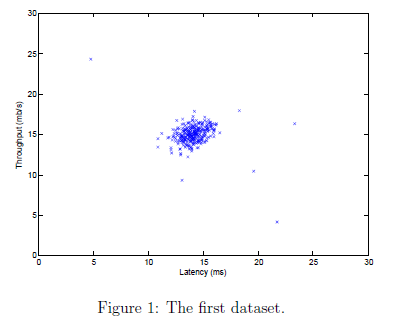

    You will use a Gaussian model to detect anomalous examples in your dataset. You will first start on a 2D dataset that will allow you to visualize what the algorithm is doing. On that dataset you will fit a Gaussian distribution and then find values that have very low probability and hence can be considered anomalies. After that, you will apply the anomaly detection algorithm to a larger dataset with many dimensions. The code below will visualize the dataset as shown in Figure 1.

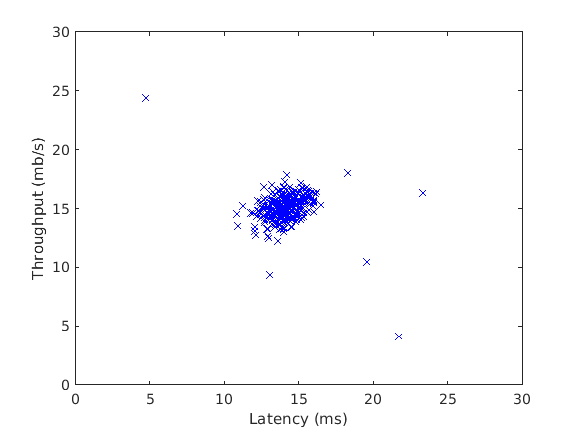

% The following command loads the dataset. You should now have the variables X, Xval, yval in your environment
load('ex8data1.mat');

% Visualize the example dataset
plot(X(:, 1), X(:, 2), 'bx');
axis([0 30 0 30]);
xlabel('Latency (ms)');
ylabel('Throughput (mb/s)');

### 1.1 Gaussian distribution

To perform anomaly detection, you will first need to fit a model to the data's distribution. Given a training set $\{x^{(1)},\dots,x^{(m)}\}$ (where $x^{(i)}\in\mathbb{R}^n$), you want to estimate the Gaussian distribution for each of the features $x_i$. For each feature $i = 1\ldots n$ you need to find parameters $\mu_i$ and $\sigma^2_i$ that fit the data in the $i$-th dimension $\{x_i^{(1)},\ldots,x^{(m)}_i\}$(the $i$-th dimension of each example).

    The Gaussian distribution is given by


$$p(x;\mu,\sigma^2)=\frac{1}{\sqrt{2\pi\sigma^2}}e^{-\frac{(x-\mu)^2}{2\sigma^2}}$$


where $\mu$ is the mean and $\sigma^2$ controls the variance.

### 1.2 Estimating parameters for a Gaussian

You can estimate the parameters, $(\mu_i,\sigma_i^2)$, of the $i$-th feature by using the following equations. To estimate the mean, you will use:

$\mu_i = \frac{1}{m}\sum_{j=1}^m{x^{(j)}}$,

and for the variance you will use:

$\sigma^2_i = \frac{1}{m}\sum_{j=1}^m{(x^{(j)}-\mu_j)^2}$.

Your task is to complete the code in `estimateGaussian.m`. This function takes as input the data matrix `X` and should output an $n$-dimension vector `mu` that holds the mean of all the $n$ features and another $n$-dimension vector `sigma2` that holds the variances of all the features. You can implement this using a `for `loop over every feature and every training example (though a vectorized implementation might be more efficient; feel free to use a vectorized implementation if you prefer). Note that in MATLAB, the `var` function will (by default) use $\frac{1}{m-1}$, instead of $\frac{1}{m}$ when computing $\sigma^2_i$.

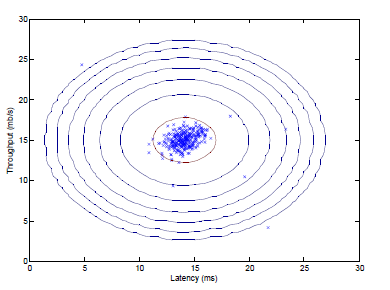

    Once you have completed the code in `estimateGaussian.m`, the code below will visualize the contours of the fitted Gaussian distribution. You should get a plot similar to Figure 2. From your plot, you can see that most of the examples are in the region with the highest probability, while the anomalous examples are in the regions with lower probabilities.

%  Estimate mu and sigma2
[mu, sigma2] = estimateGaussian(X)

mu =    14.1122
   14.9977


sigma2 =     1.8326
    1.7097


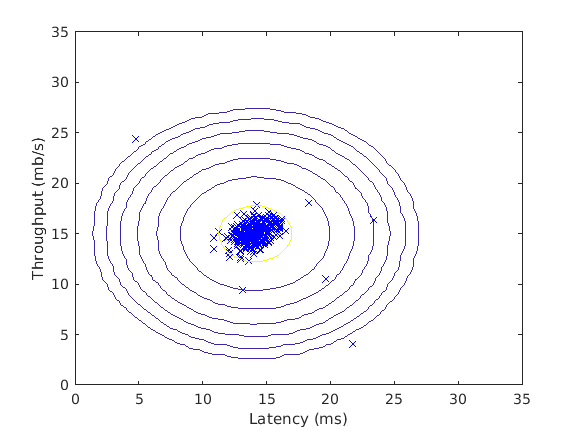


%  Returns the density of the multivariate normal at each data point (row) of X
p = multivariateGaussian(X, mu, sigma2);

%  Visualize the fit
visualizeFit(X,  mu, sigma2);
xlabel('Latency (ms)');
ylabel('Throughput (mb/s)');

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

### 1.3 Selecting the threshold, $\epsilon$

Now that you have estimated the Gaussian parameters, you can investigate which examples have a very high probability given this distribution and which examples have a very low probability. The low probability examples are more likely to be the anomalies in our dataset. One way to determine which examples are anomalies is to select a threshold based on a cross validation set. In this part of the exercise, you will implement an algorithm to select the threshold $\epsilon$ using the $F_1$ score on a cross validation set.

    You should now complete the code in `selectThreshold.m`. For this, we will use a cross validation set $\{(x^{(1)}_{cv},y^{(1)}_{cv}),\ldots, (x^{(m)}_{cv},y^{(m)}_{cv})\}$, where the label $y = 1$ corresponds to an anomalous example, and $y = 0$ corresponds to a normal example. For each cross validation example, we will compute $p(x^{(i)}_{cv})$. The vector of all of these probabilities $p(x^{(1)}_{cv}),\ldots,p(x^{(m)}_{cv})$ is passed to `selectThreshold.m` in the vector `pval`. The corresponding labels $y^{(1)}_{cv},\ldots,y^{m)}_{cv}$ is passed to the same function in the vector `yval`.

    The function `selectThreshold.m` should return two values; the first is the selected threshold $\epsilon$. If an example $x$ has a low probability $p(x) < \epsilon$, then it is considered to be an anomaly. The function should also return the $F_1$ score, which tells you how well you're doing on finding the ground truth anomalies given a certain threshold. For many different values of $\epsilon$, you will compute the resulting $F_1$ score by computing how many examples the current threshold classifies correctly and incorrectly.

    The $F_1$ score is computed using precision (*prec*) and recall (*rec*):

$F_1 = \frac{2 ( prec)(rec)}{prec + rec}$,

You compute precision and recall by:


$$prec = \frac{tp}{tp + fp}$$



$$rec = \frac{tp}{tp + fn}$$


where

- $tp$ is the number of true positives: the ground truth label says it's an anomaly and our algorithm correctly classified it as an anomaly.

- $fp$ is the number of false positives: the ground truth label says it's not an anomaly, but our algorithm incorrectly classified it as an anomaly.

- $fn$ is the number of false negatives: the ground truth label says it's an anomaly, but our algorithm incorrectly classified it as not being anomalous.

In the provided code `selectThreshold.m`, there is already a loop that will try many different values of $\epsilon$ and select the "best" based $\epsilon$ on the $F_1$ score. You should now complete the code in `selectThreshold.m`. You can implement the computation of the $F_1$ score using a `for` loop over all the cross validation examples (to compute the values $tp,\; fp,\text{and }fn$. You should see a value for epsilon of about `8.99e-05`.

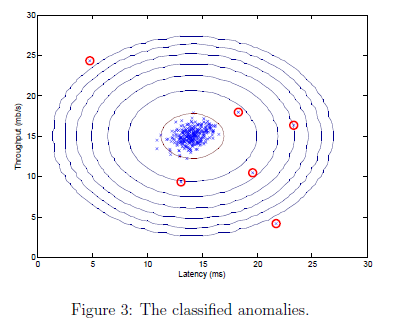

**Implementation Note**: In order to compute $tp,\; fp,\text{and }fn$, you may be able to use a vectorized implementation rather than loop over all the examples. This can be implemented by MATLAB's equality test between a vector and a single number. If you have several binary values in an $n$-dimensional binary vector $v\in\{0,\;1\}^n$, you can find out how many values in this vector are 0 by using: `sum(v == 0)`. You can also apply a logical `and` operator to such binary vectors. For instance, let `cvPredictions` be a binary vector of the size of your cross validation set, where the $i$-th element is 1 if your algorithm considers $x^{(i)}_{cv}$ an anomaly, and 0 otherwise. You can then, for example, compute the number of false positives using:` fp = sum((cvPredictions == 1) & (yval == 0))`.

    Once you have completed the code in `selectThreshold.m`, the code below will detect and circle the anomalies in the plot (Figure 3).

pval = multivariateGaussian(Xval, mu, sigma2);

[epsilon, F1] = selectThreshold(yval, pval);
fprintf('Best epsilon found using cross-validation: %e\n', epsilon);

Best epsilon found using cross-validation: 8.990853e-05


fprintf('Best F1 on Cross Validation Set:  %f\n', F1);

Best F1 on Cross Validation Set:  0.875000


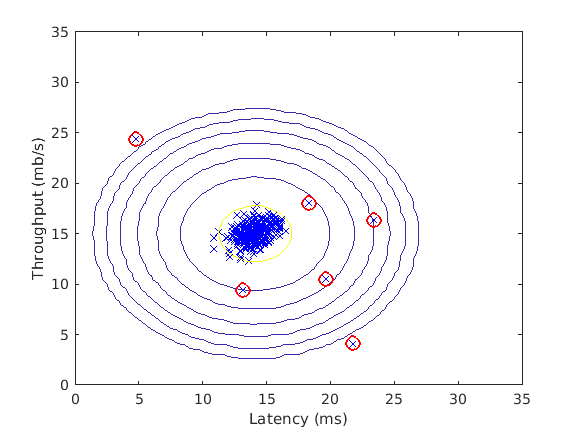


%  Find the outliers in the training set and plot the
outliers = find(p < epsilon);

%  Visualize the fit
visualizeFit(X,  mu, sigma2);
xlabel('Latency (ms)');
ylabel('Throughput (mb/s)');
%  Draw a red circle around those outliers
hold on
plot(X(outliers, 1), X(outliers, 2), 'ro', 'LineWidth', 2, 'MarkerSize', 10);
hold off

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

### 1.4 High dimensional dataset

The code in this section will run the anomaly detection algorithm you implemented on a more realistic and much harder dataset. In this dataset, each example is described by 11 features, capturing many more properties of your compute servers. The code below will use your code to estimate the Gaussian parameters ($\mu_i$ and $\sigma^2_i$), evaluate the probabilities for both the training data `X` from which you estimated the Gaussian parameters, and do so for the the cross-validation set `Xval`. Finally, it will use `selectThreshold` to find the best threshold $\epsilon$. You should see a value `epsilon` of about `1.38e-18`, and 117 anomalies found.

%  Loads the second dataset. You should now have the variables X, Xval, yval in your environment
load('ex8data2.mat');

%  Apply the same steps to the larger dataset
[mu, sigma2] = estimateGaussian(X);

%  Training set 
p = multivariateGaussian(X, mu, sigma2);

%  Cross-validation set
pval = multivariateGaussian(Xval, mu, sigma2);

%  Find the best threshold
[epsilon, F1] = selectThreshold(yval, pval);
fprintf('Best epsilon found using cross-validation: %e\n', epsilon);

Best epsilon found using cross-validation: 1.377229e-18


fprintf('Best F1 on Cross Validation Set:  %f\n', F1);

Best F1 on Cross Validation Set:  0.615385


fprintf('# Outliers found: %d\n', sum(p < epsilon));

# Outliers found: 117


## 2. Recommender Systems

In this part of the exercise, you will implement the collaborative filtering learning algorithm and apply it to a dataset of movie ratings*. This dataset consists of ratings on a scale of 1 to 5. The dataset has $n_u = 943$ users, and $n_m = 1682$ movies. In the next parts of this exercise, you will implement the function `cofiCostFunc.m` that computes the collaborative fitlering objective function and gradient. After implementing the cost function and gradient, you will use `fmincg.m` to learn the parameters for collaborative filtering.

*[MovieLens 100k Dataset](https://grouplens.org/datasets/movielens/) from GroupLens Research.

### 2.1 Movie ratings dataset

The code in this section will load the dataset `ex8_movies.mat`, providing the variables `Y` and `R` in your MATLAB environment. The matrix `Y` (a `num_movies` $\times$ `num_users` matrix) stores the ratings $y^{(i,j)}$ (from 1 to 5). The matrix `R` is an binary-valued indicator matrix, where` R(i,j) = 1` if user `j` gave a rating to movie `i`, and `R(i,j) = 0` otherwise. The objective of collaborative filtering is to predict movie ratings for the movies that users have not yet rated, that is, the entries with `R(i,j) = 0`. This will allow us to recommend the movies with the highest predicted ratings to the user.

    To help you understand the matrix `Y`, the code below will compute the average movie rating for the first movie (Toy Story) and output the average rating to the screen. Throughout this part of the exercise, you will also be working with the matrices, `X` and `Theta`:

`X = `$\left\lbrack \begin{array}{c}
-{\;\left(x^{\left(1\right)} \right)}^T -\\
-{\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\;\left(x^{\left(n_m \right)} \right)}^T -
\end{array}\right\rbrack$,    `Theta = `$\left\lbrack \begin{array}{c}
-{\;\left(\theta^{\left(1\right)} \right)}^T -\\
-{\;\left(\theta^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\;\left(\theta^{\left(n_u \right)} \right)}^T -
\end{array}\right\rbrack$.

% Load data
load('ex8_movies.mat');

- `Y` is a 1682 x 943 matrix, containing ratings (1 - 5) of 1682 movies on 943 users

- `R` is a 1682 x 943 matrix, where `R(i,j)` = 1 if and only if user `j` gave a rating to movie `i`

% From the matrix, we can compute statistics like average rating.
fprintf('Average rating for movie 1 (Toy Story): %f / 5\n\n', mean(Y(1, R(1, :))));

Average rating for movie 1 (Toy Story): 3.878319 / 5



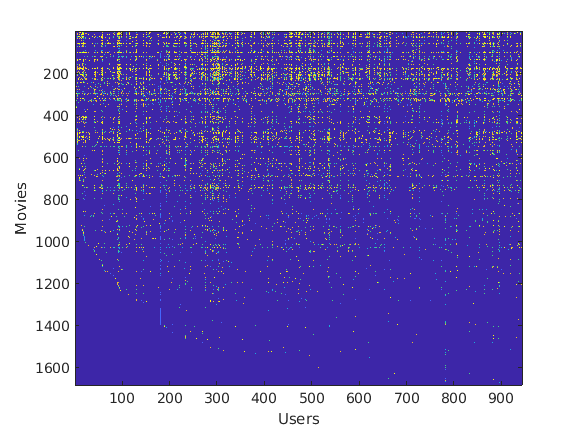

%  We can "visualize" the ratings matrix by plotting it with imagesc
imagesc(Y);
ylabel('Movies');
xlabel('Users');

The $i$-th row of `X` corresponds to the feature vector $x^{(i)}$ for the $i$-th movie, and the $j$-th row of `Theta` corresponds to one parameter vector $\theta^{(j)}$, for the $j$-th user. Both $x^{(i)}$ and $\theta^{(j)}$ are $n$-dimensional vectors. For the purposes of this exercise, you will use $n = 100$, and therefore, $x^{(i)} \in\mathbb{R}^{100}$ and $\theta^{(j)} \in\mathbb{R}^{100}$. Correspondingly, `X` is a $n_m\times 100$ matrix and `Theta` is a $n_u\times 100$ matrix.

### 2.2 Collaborative filtering learning algorithm

Now, you will start implementing the collaborative filtering learning algorithm. You will start by implementing the cost function (without regularization). The collaborative filtering algorithm in the setting of movie recommendations considers a set of $n$-dimensional parameter vectors $x^{(1)},\ldots,x^{(n_m)}$ and $\theta^{(1)},\ldots, \theta^{(n_u)}$, where the model predicts the rating for movie $i$ by user $j$ as $y^{(i,j)} = (\theta^{(j)})^T x^{(i)}$. Given a dataset that consists of a set of ratings produced by some users on some movies, you wish to learn the parameter vectors $x^{(1)},\ldots,x^{(n_m)},\;\theta^{(1)},\ldots,\theta^{(n_u)}$ that produce the best fit (minimizes the squared error).

    You will complete the code in `cofiCostFunc.m` to compute the cost function and gradient for collaborative filtering. Note that the parameters to the function (i.e., the values that you are trying to learn) are `X` and `Theta`. In order to use an off-the-shelf minimizer such as `fmincg`, the cost function has been set up to unroll the parameters into a single vector `params`. You had previously used the same vector unrolling method in the neural networks programming exercise.

#### 2.2.1 Collaborative filtering cost function

The collaborative filtering cost function (without regularization) is given by


$$J\left(x^{(i)},\ldots,x^{(n_m)},\;\theta^{(1)},\ldots,\theta^{(n_u)}\right)
=\frac{1}{2}\sum_{(i,j):r(i,j)=1}\left((\theta^{(j)})^Tx^{(i)}-y^{(i,j)}\right)^2$$


You should now modify `cofiCostFunc.m` to return this cost in the variable `J`. Note that you should be accumulating the cost for user $j$ and movie $i$ only if $R(i,j) = 1$. After you have completed the function, the code below will run your cost function. You should expect to see an output of `22.22`.

**Implementation Note:** We strongly encourage you to use a vectorized implementation to compute `J`, since it will later by called many times by the optimization package `fmincg`. As usual, it might be easiest to first write a non-vectorized implementation (to make sure you have the right answer), and the modify it to become a vectorized implementation (checking that the vectorization steps don't change your algorithm's output). To come up with a vectorized implementation, the following tip might be helpful: You can use the `R` matrix to set selected entries to 0. For example, `R.*M` will do an element-wise multiplication between `M` and `R`; since `R` only has elements with values either 0 or 1, this has the effect of setting the elements of `M` to 0 only when the corresponding value in `R` is 0. Hence, `sum(sum(R.*M))` is the sum of all the elements of `M` for which the corresponding element in `R` equals 1.

%  Load pre-trained weights (X, Theta, num_users, num_movies, num_features)
load('ex8_movieParams.mat');

%  Reduce the data set size so that this runs faster
num_users = 4; num_movies = 5; num_features = 3;
X = X(1:num_movies, 1:num_features);
Theta = Theta(1:num_users, 1:num_features);
Y = Y(1:num_movies, 1:num_users);
R = R(1:num_movies, 1:num_users);

%  Evaluate cost function
J = cofiCostFunc([X(:); Theta(:)],  Y, R, num_users, num_movies,num_features, 0);
fprintf('Cost at loaded parameters: %f ',J);

Cost at loaded parameters: 22.224604 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 2.2.2 Collaborative filtering gradient

Now, you should implement the gradient (without regularization). Specically, you should complete the code in `cofiCostFunc.`m to return the variables `X_grad` and `Theta_gra`d. Note that `X_grad` should be a matrix of the same size as `X` and similarly, `Theta_grad` is a matrix of the same size as `Theta`. The gradients of the cost function is given by:


$$\frac{\partial J}{\partial x_k^{(i)}} 
= \sum_{j:r(i,j)=1}\left((\theta^{(j)})^T x^{(i)} -y^{(i,j)}\right)\theta_k^{(j)}$$



$$\frac{\partial J}{\partial \theta_k^{(j)}} = \sum_{i:r(i,j)=1}\left((\theta^{(j)})^T x^{(i)} -y^{(i,j)}\right) x_k^{(i)}$$


Note that the function returns the gradient for both sets of variables by unrolling them into a single vector. After you have completed the code to compute the gradients, the code below will run a gradient check (`checkCostFunction`) to numerically check the implementation of your gradients. (This is similar to the numerical check that you used in the neural networks exercise.) If your implementation is correct, you should find that the analytical and numerical gradients match up closely.

**Implementation Note**: You can get full credit for this assignment without using a vectorized implementation, but your code will run much more slowly (a small number of hours), and so we recommend that you try to vectorize your implementation. To get started, you can implement the gradient with a `for` loop over movies (for computing $\frac{\partial J}{\partial x_k^{(i)}$) and a `for` loop over users (for computing $\frac{\partial J}{\partial \theta_k^{(j)}$). When you first implement the gradient, you might start with an unvectorized version, by implementing another inner `for` loop that computes each element in the summation. After you have completed the gradient computation this way, you should try to vectorize your implementation (vectorize the inner `for` loops), so that you're left with only two `for` loops (one for looping over movies to compute $\frac{\partial J}{\partial x_k^{(i)}$ for each movie, and one for looping over users to compute $\frac{\partial J}{\partial \theta_k^{(j)}$ for each user).

    To perform the vectorization, you might find this helpful: You should come up with a way to compute all the derivatives associated with $x^{(i)}_1,x^{(i)}_2,\ldots,x^{(i)}_n$, (i.e., the derivative terms associated with the feature vector $x^{(i)}$) at the same time. Let us define the derivatives for the feature vector of the $i$-th movie as:


$${\left({\mathrm{X}}_{\textrm{grad}} \left(\mathrm{i},:\right)\right)}^T =\left\lbrack \begin{array}{c}
\frac{\partial J}{\partial x_1^{\left(i\right)} }\\
\frac{\partial J}{\partial x_2^{\left(i\right)} }\\
\vdots \\
\frac{\partial J}{\partial x_n^{\left(i\right)} }
\end{array}\right\rbrack =\sum_{j:r\left(i,j\right)=1} \left({\left(\theta^{\left(j\right)} \right)}^T x^{\left(i\right)} -y^{\left(i,j\right)} \right)\;\theta^{\left(j\right)}$$


To vectorize the above expression, you can start by indexing into `Theta` and `Y` to select only the elements of interest (that is, those with $r(i,j) = 1$). Intuitively, when you consider the features for the $i$-th movie, you only need to be concerned about the users who had given ratings to the movie, and this allows you to remove all the other users from `Theta` and `Y`.

    Concretely, you can set `idx = find(R(i,:)==1)` to be a list of all the users that have rated movie $i$. This will allow you to create the temporary matrices `Theta_temp = Theta(idx,:)` and `Y_temp = Y(i,idx)` that index into `Theta` and `Y` to give you only the set of users which have rated the $i$-th movie. This will allow you to write the derivatives as:

${\mathrm{X}}_{\textrm{grad}} \left(i,:\right)=\left(\mathrm{X}\left(i,:\right)*{\textrm{Theta}}_{\textrm{temp}}^T -{\mathrm{Y}}_{\textrm{temp}} \right)*{\textrm{Theta}}_{\textrm{temp}}$.

(Note: The vectorized computation above returns a row-vector instead.) After you have vectorized the computations of the derivatives with respect to $x^{(i)}$, you should use a similar method to vectorize the derivatives with respect to $\theta^{(j)}$ as well.

%  Check gradients by running checkNNGradients
checkCostFunction;

    2.3643    2.3643
    0.9869    0.9869
    6.4476    6.4476
    0.5500    0.5500
    2.2468    2.2468
    0.1664    0.1664
    6.5569    6.5569
   -1.3343   -1.3343
   -0.7755   -0.7755
   -1.4683   -1.4683
   -2.0644   -2.0644
    1.7313    1.7313
   -1.1679   -1.1679
   -0.1094   -0.1094
   -8.0833   -8.0833
   -0.3705   -0.3705
    0.3625    0.3625
    0.8582    0.8582
    1.2042    1.2042
    0.9944    0.9944
    0.6570    0.6570
   -0.4032   -0.4032
    0.2724    0.2724
    0.2161    0.2161
   -0.4910   -0.4910
    0.1517    0.1517
    0.0830    0.0830

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your cost function implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 7.65313e-13


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 2.2.3 Regularized cost function

The cost function for collaborative filtering with regularization is given by


$$J\left(x^{(i)},\ldots,x^{(n_m)},\;\theta^{(1)},\ldots,\theta^{(n_u)}\right)
=\frac{1}{2}\sum_{(i,j):r(i,j)=1}\left((\theta^{(j)})^Tx^{(i)}-y^{(i,j)}\right)^2
+\left(\frac{\lambda}{2}\sum_{j=1}^{n_u}{\sum_{k=1}^{n}{(\theta_k^{(j)})^2}}\right)
+\left(\frac{\lambda}{2}\sum_{i=1}^{n_m}{\sum_{k=1}^{n}{(x_k^{(i)})^2}}\right)$$


You should now add regularization to your original computations of the cost function, $J$. After you are done, the code below will run your regularized cost function, and you should expect to see a cost of about `31.34`.

%  Evaluate cost function
J = cofiCostFunc([X(:); Theta(:)], Y, R, num_users, num_movies, num_features, 1.5);      
fprintf('Cost at loaded parameters (lambda = 1.5): %f',J);

Cost at loaded parameters (lambda = 1.5): 31.344056

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 2.2.4 Regularized gradient

Now that you have implemented the regularized cost function, you should proceed to implement regularization for the gradient. You should add to your implementation in `cofiCostFunc.m` to return the regularized gradient by adding the contributions from the regularization terms. Note that the gradients for the regularized cost function is given by:


$$\frac{\partial J}{\partial x_k^{(i)}} 
= \sum_{j:r(i,j)=1}\left((\theta^{(j)})^T x^{(i)} -y^{(i,j)}\right)\theta_k^{(j)}+\lambda x_k^{(i)}$$



$$\frac{\partial J}{\partial \theta_k^{(j)}} = \sum_{i:r(i,j)=1}\left((\theta^{(j)})^T x^{(i)} -y^{(i,j)}\right) x_k^{(i)}+\lambda\theta_k^{(j)}$$


This means that you just need to add $\lambda x^{(i)}$ to the `X_grad(i,:)` variable described earlier, and add $\lambda \theta^{(j)}$ to the `Theta_grad(j,:) `variable described earlier. After you have completed the code to compute the gradients, the code below will run another gradient check (`checkCostFunction`) to numerically check the implementation of your gradients.

%  Check gradients by running checkNNGradients
checkCostFunction(1.5);

    0.1357    0.1357
   -0.2943   -0.2943
    0.2902    0.2902
  -11.1904  -11.1904
   -1.5782   -1.5782
   -9.6423   -9.6423
   -2.5057   -2.5057
  -11.9702  -11.9702
    0.7678    0.7678
   -3.0279   -3.0279
   -2.2229   -2.2229
  -13.5334  -13.5334
   -2.8039   -2.8039
    2.4642    2.4642
    6.3481    6.3481
    1.8480    1.8480
    7.4026    7.4026
    5.4160    5.4160
    4.6305    4.6305
    2.0397    2.0397
   -3.3406   -3.3406
   13.7947   13.7947
    0.4775    0.4775
    5.0806    5.0806
    4.0659    4.0659
    0.2790    0.2790
   12.2185   12.2185

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your cost function implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 1.83757e-12


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

### 2.3 Learning movie recommendations

After you have finished implementing the collaborative ltering cost function and gradient, you can now start training your algorithm to make movie recommendations for yourself. In the code below, you can enter your own movie preferences, so that later when the algorithm runs, you can get your own movie recommendations! We have filled out some values according to our own preferences, but you should change this according to your own tastes. The list of all movies and their number in the dataset can be found listed in the file movie idx.txt.

% Load movvie list
movieList = loadMovieList();

% Initialize my ratings
my_ratings = zeros(1682, 1);

% Check the file movie_idx.txt for id of each movie in our dataset
% For example, Toy Story (1995) has ID 1, so to rate it "4", you can set
my_ratings(1) = 4;
% Or suppose did not enjoy Silence of the Lambs (1991), you can set
my_ratings(98) = 2; 

% We have selected a few movies we liked / did not like and the ratings we gave are as follows:
my_ratings(7) = 3;
my_ratings(12)= 5;
my_ratings(54) = 4;
my_ratings(64)= 5;
my_ratings(66)= 3;
my_ratings(69) = 5;
my_ratings(183) = 4;
my_ratings(226) = 5;
my_ratings(355)= 5;

fprintf('\n\nNew user ratings:\n');



New user ratings:


for i = 1:length(my_ratings)
    if my_ratings(i) > 0 
        fprintf('Rated %d for %s\n', my_ratings(i), movieList{i});
    end
end

Rated 4 for Toy Story (1995)
Rated 3 for Twelve Monkeys (1995)
Rated 5 for Usual Suspects, The (1995)
Rated 4 for Outbreak (1995)
Rated 5 for Shawshank Redemption, The (1994)
Rated 3 for While You Were Sleeping (1995)
Rated 5 for Forrest Gump (1994)
Rated 2 for Silence of the Lambs, The (1991)
Rated 4 for Alien (1979)
Rated 5 for Die Hard 2 (1990)
Rated 5 for Sphere (1998)


#### 2.3.1 Recommendations

After the additional ratings have been added to the dataset, the code below will proceed to train the collaborative filtering model. This will learn the parameters `X` and `Theta`. 

%  Load data
load('ex8_movies.mat');

%  Y is a 1682x943 matrix, containing ratings (1-5) of 1682 movies by 943 users
%  R is a 1682x943 matrix, where R(i,j) = 1 if and only if user j gave a rating to movie i
%  Add our own ratings to the data matrix
Y = [my_ratings Y];
R = [(my_ratings ~= 0) R];

%  Normalize Ratings
[Ynorm, Ymean] = normalizeRatings(Y, R);

%  Useful Values
num_users = size(Y, 2);
num_movies = size(Y, 1);
num_features = 10;

% Set Initial Parameters (Theta, X)
X = randn(num_movies, num_features);
Theta = randn(num_users, num_features);
initial_parameters = [X(:); Theta(:)];

% Set options for fmincg
options = optimset('GradObj','on','MaxIter',100);

% Set Regularization
lambda = 10;
theta = fmincg(@(t)(cofiCostFunc(t, Ynorm, R, num_users, num_movies, num_features,lambda)), initial_parameters, options);

Iteration     1 | Cost: 3.151396e+05
Iteration     2 | Cost: 1.432044e+05
Iteration     3 | Cost: 1.032920e+05
Iteration     4 | Cost: 9.529716e+04
Iteration     5 | Cost: 8.656718e+04
Iteration     6 | Cost: 6.512896e+04
Iteration     7 | Cost: 5.395301e+04
Iteration     8 | Cost: 4.961176e+04
Iteration     9 | Cost: 4.555943e+04
Iteration    10 | Cost: 4.361082e+04
Iteration    11 | Cost: 4.223085e+04
Iteration    12 | Cost: 4.139260e+04
Iteration    13 | Cost: 4.105914e+04
Iteration    14 | Cost: 4.063536e+04
Iteration    15 | Cost: 4.025821e+04
Iteration    16 | Cost: 4.011235e+04
Iteration    17 | Cost: 4.006373e+04
Iteration    18 | Cost: 3.976638e+04
Iteration    19 | Cost: 3.967576e+04
Iteration    20 | Cost: 3.955903e+04
Iteration    21 | Cost: 3.950061e+04
Iteration    22 | Cost: 3.947398e+04
Iteration    23 | Cost: 3.938330e+04
Iteration    24 | Cost: 3.936043e+04
Iteration    25 | Cost: 3.934078e+04
Iteration    26 | Cost: 3.926151e+04
Iteration    27 | Cost: 3.922624e+04
I


% Unfold the returned theta back into U and W
X = reshape(theta(1:num_movies*num_features), num_movies, num_features);
Theta = reshape(theta(num_movies*num_features+1:end), num_users, num_features);


To predict the rating of movie $i$ for user$j$, you need to compute $(\theta^{(j)})^T x^{(i)}$ The code below computes the ratings for all the movies and users and displays the movies that it recommends (Figure 4), according to ratings that were entered earlier in the script. Note that you might obtain a different set of the predictions due to different random initializations.

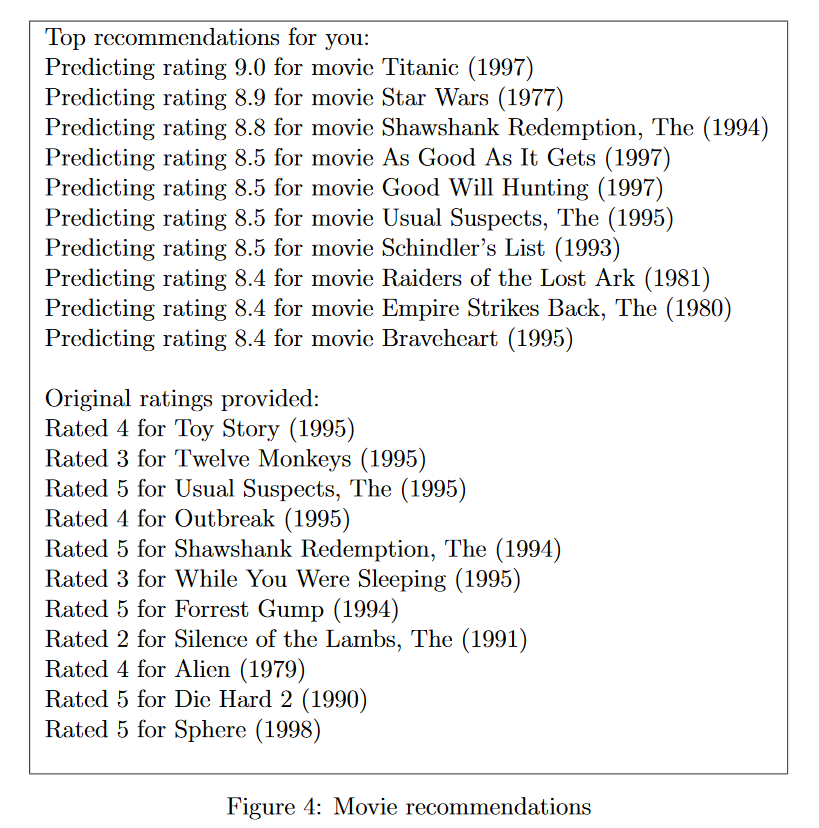

p = X * Theta';
my_predictions = p(:,1) + Ymean;

movieList = loadMovieList();

[r, ix] = sort(my_predictions,'descend');
for i=1:10
    j = ix(i);
    if i == 1
        fprintf('\nTop recommendations for you:\n');
    end
    fprintf('Predicting rating %.1f for movie %s\n', my_predictions(j), movieList{j});
end


Top recommendations for you:


Predicting rating 5.0 for movie Star Kid (1997)
Predicting rating 5.0 for movie Prefontaine (1997)
Predicting rating 5.0 for movie They Made Me a Criminal (1939)
Predicting rating 5.0 for movie Entertaining Angels: The Dorothy Day Story (1996)
Predicting rating 5.0 for movie Great Day in Harlem, A (1994)
Predicting rating 5.0 for movie Santa with Muscles (1996)
Predicting rating 5.0 for movie Someone Else's America (1995)
Predicting rating 5.0 for movie Saint of Fort Washington, The (1993)
Predicting rating 5.0 for movie Marlene Dietrich: Shadow and Light (1996)
Predicting rating 5.0 for movie Aiqing wansui (1994)


for i = 1:length(my_ratings)
    if i == 1
        fprintf('\n\nOriginal ratings provided:\n');
    end
    if my_ratings(i) > 0 
        fprintf('Rated %d for %s\n', my_ratings(i), movieList{i});
    end
end



Original ratings provided:


Rated 4 for Toy Story (1995)
Rated 3 for Twelve Monkeys (1995)
Rated 5 for Usual Suspects, The (1995)
Rated 4 for Outbreak (1995)
Rated 5 for Shawshank Redemption, The (1994)
Rated 3 for While You Were Sleeping (1995)
Rated 5 for Forrest Gump (1994)
Rated 2 for Silence of the Lambs, The (1991)
Rated 4 for Alien (1979)
Rated 5 for Die Hard 2 (1990)
Rated 5 for Sphere (1998)


## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

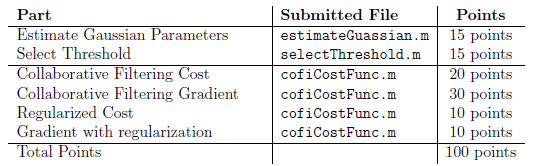

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.